# HDL Coder Optimization in Simulink

*Version:* R2025b

Use area and speed optimizations in HDL Coder™ to save resources and improve the timing of your design on the target FPGA device. The optimizations do not change the functional behavior of your algorithm but can optimize certain resources in your design, introduce latency, or cause difference in sample rates.

The example used in this demo is a multi-module phase shift generator.

Throughout the example, I will fix the configuration as follows:

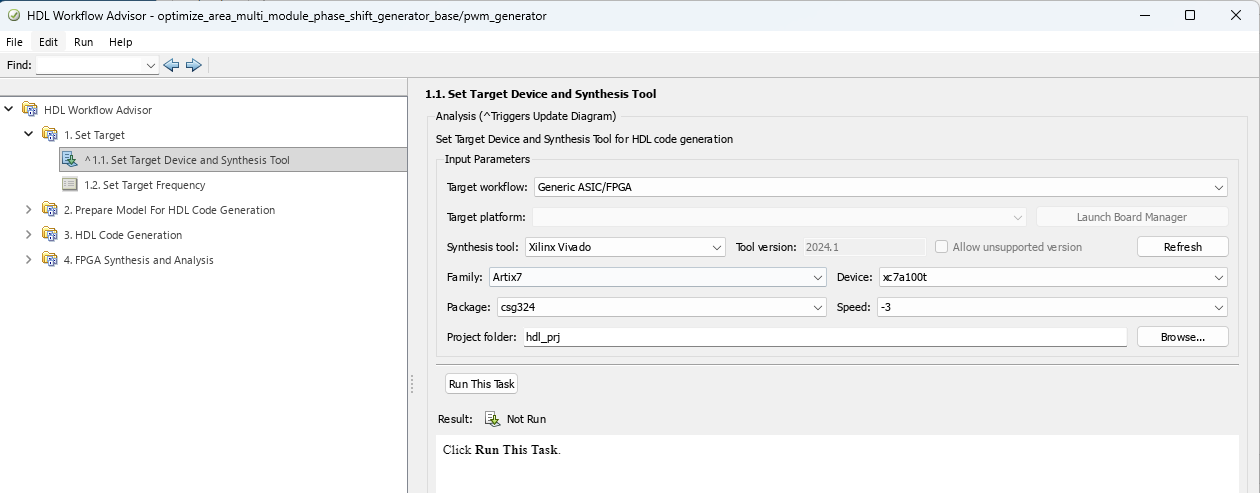

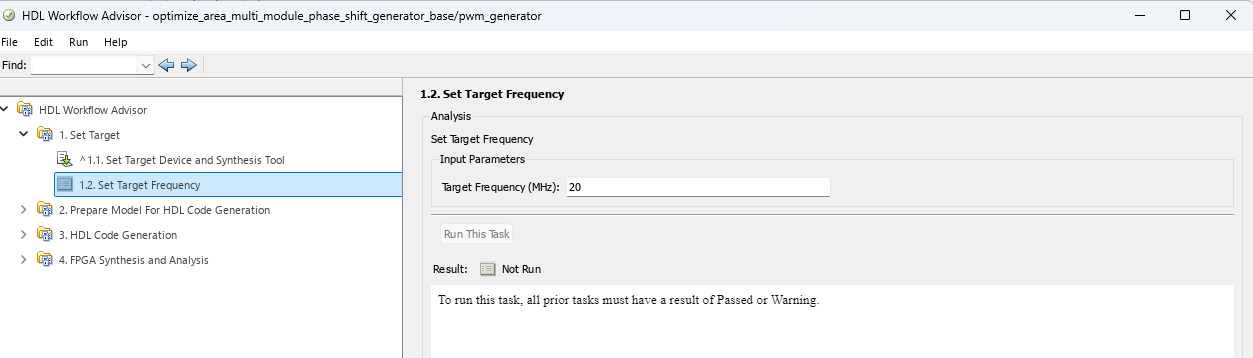

## Base Model

The idea of the first model is that the algo is generated using the most fundamental Simulink building blocks. We will optimize this example at a later stage.

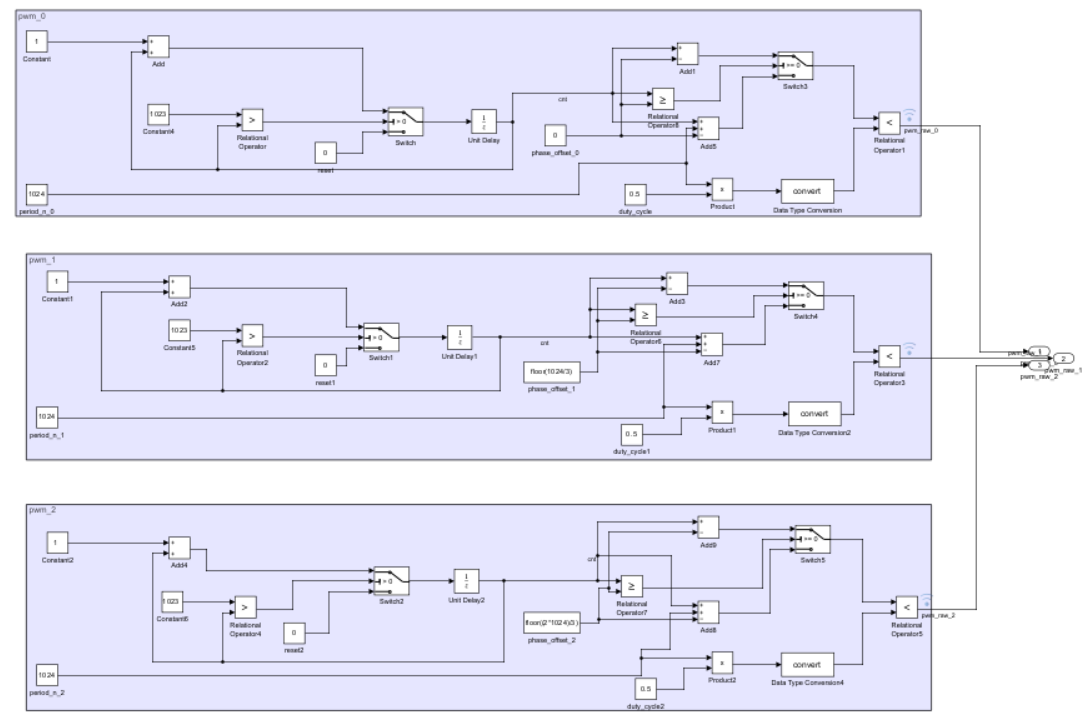

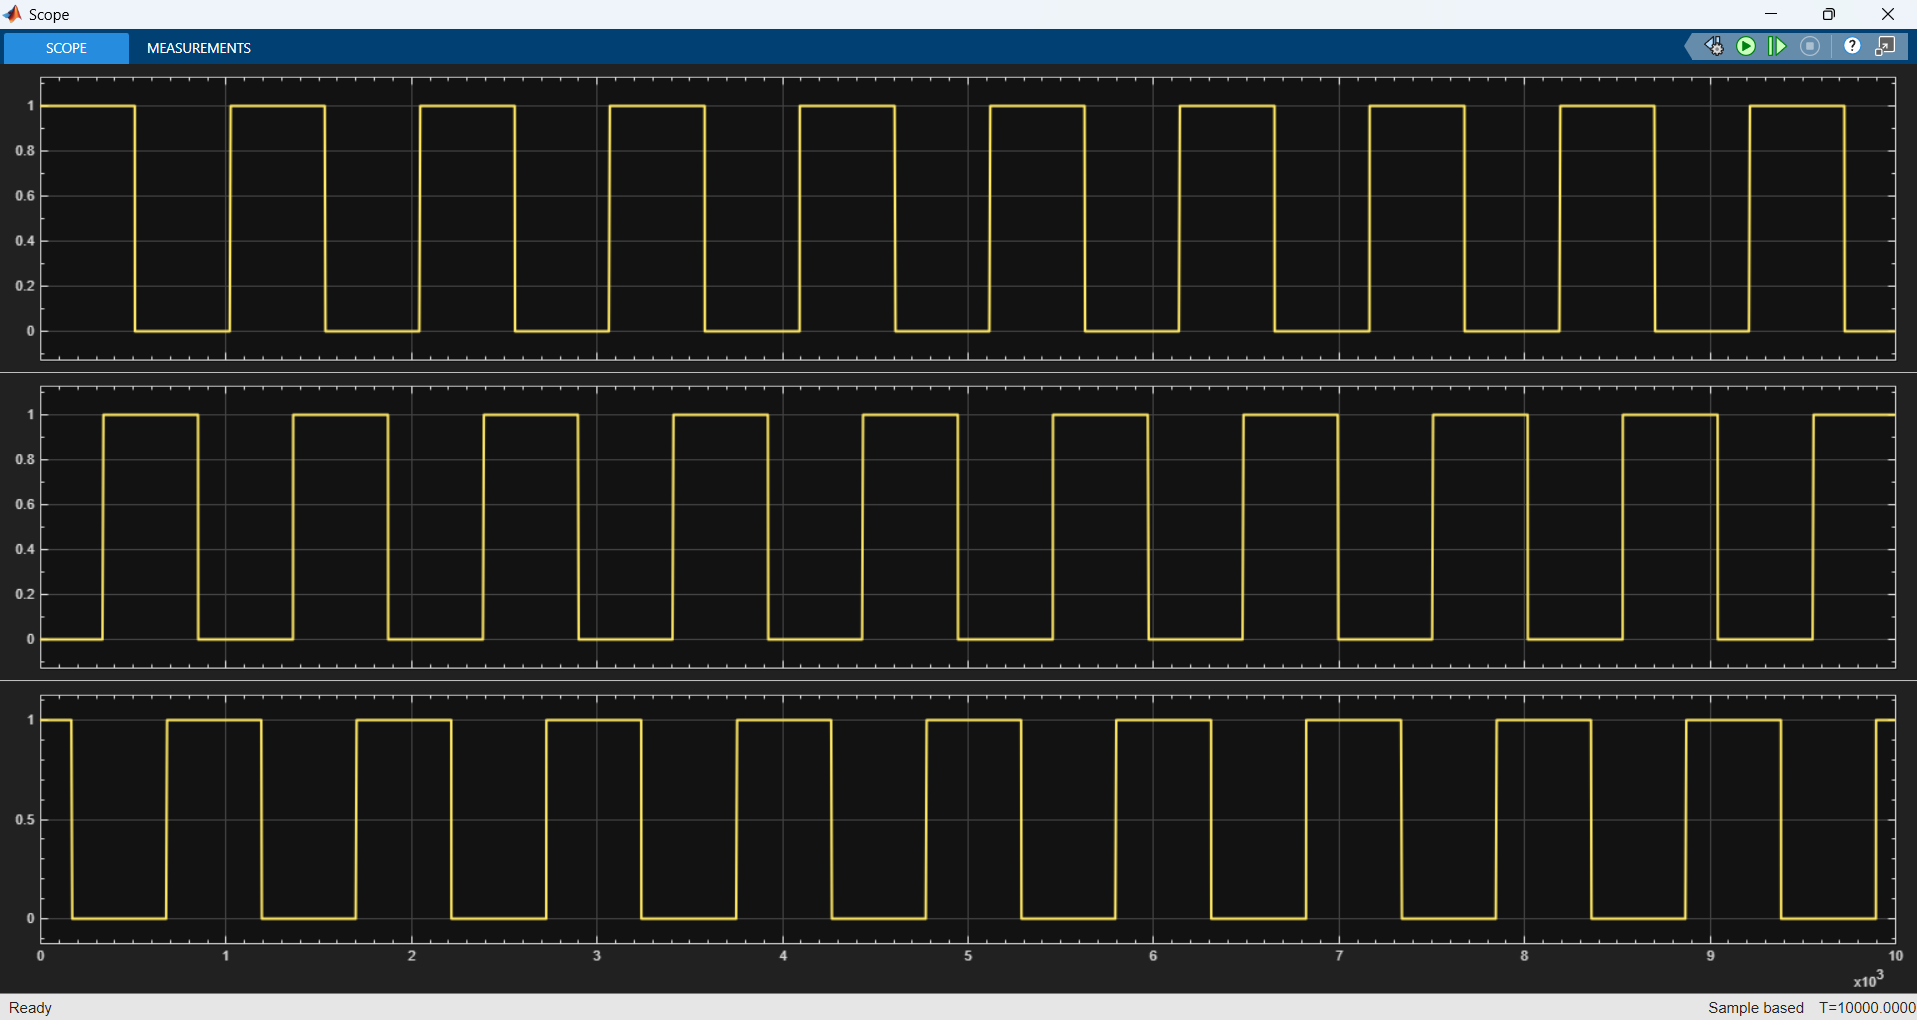

open multi_module_phase_shift_generator_base.slx

#### Resource Estimation

#### Critical Path Estimation

## **Optimization - Timing**

### **Adaptive Pipelining**

open adaptive_pipelining_multi_module_phase_shift_generator_base.slx

#### Resource Estimation

#### Critical Path Estimation

### Input/Output Pipelining + Distributed

open input_output_distributed_pipelining_multi_module_phase_shift_generator_base.slx

#### Resource Estimation

#### Critical Path Estimation

## **Optimization - Area**

### **Resource Sharing**

open resource_sharing_multi_module_phase_shift_generator_base.slx

#### Resource Estimation

#### Critical Path Estimation

## **Built-in Counter Model**

This model uses a built-in Counter to replaced the basic Simulink block. This achieves the same output even optimized result.

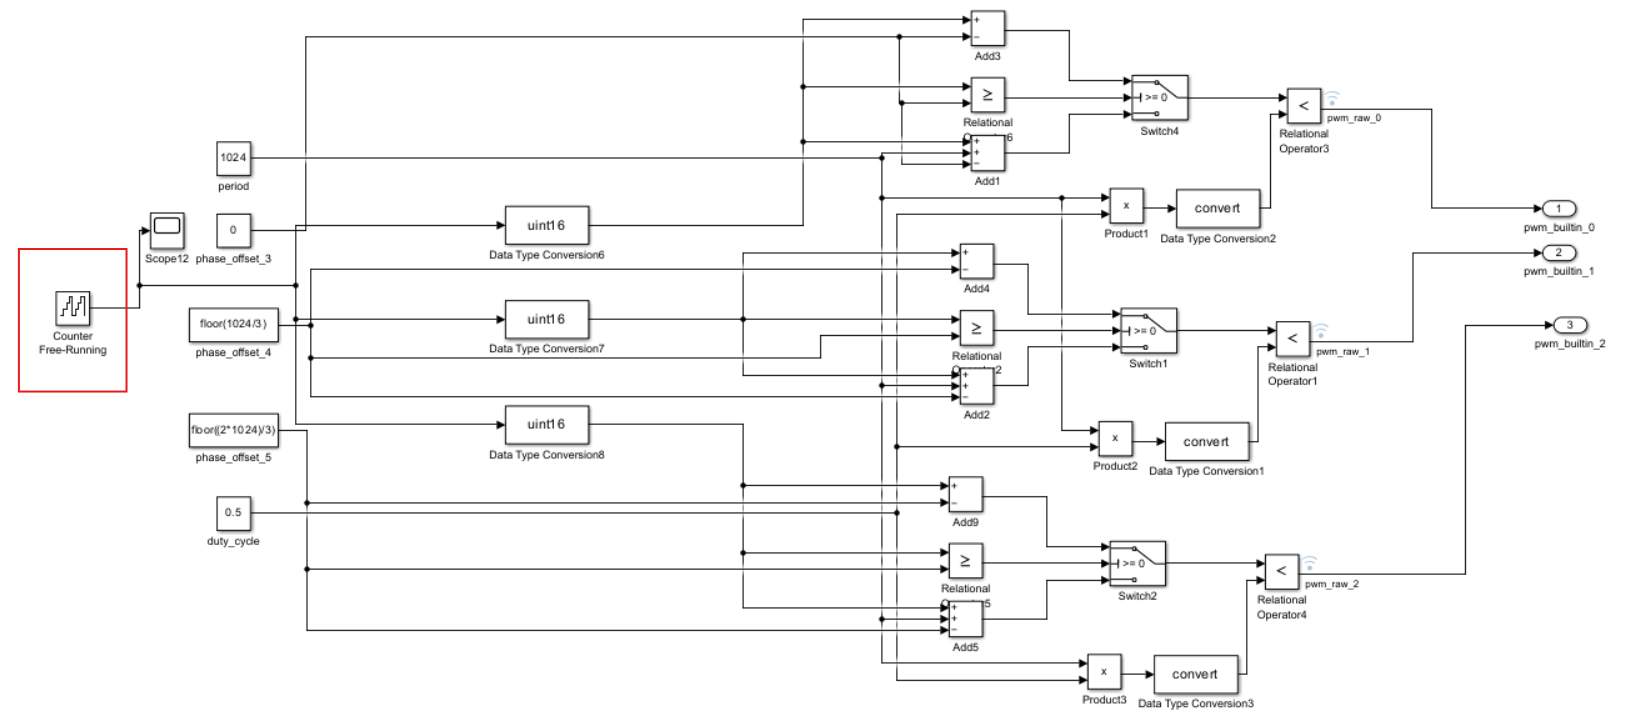

open multi_module_phase_shift_generator_built_in_counter.slx

#### Resource Estimation

#### Critical Path Estimation

## **Built-in PWM Model**

This model uses a built-in PWM block to generate similar output. However, this block only supports double as the data type. Hence model needs to be configured to use native floating point when generating code, which consumes a more significant amount of resources.

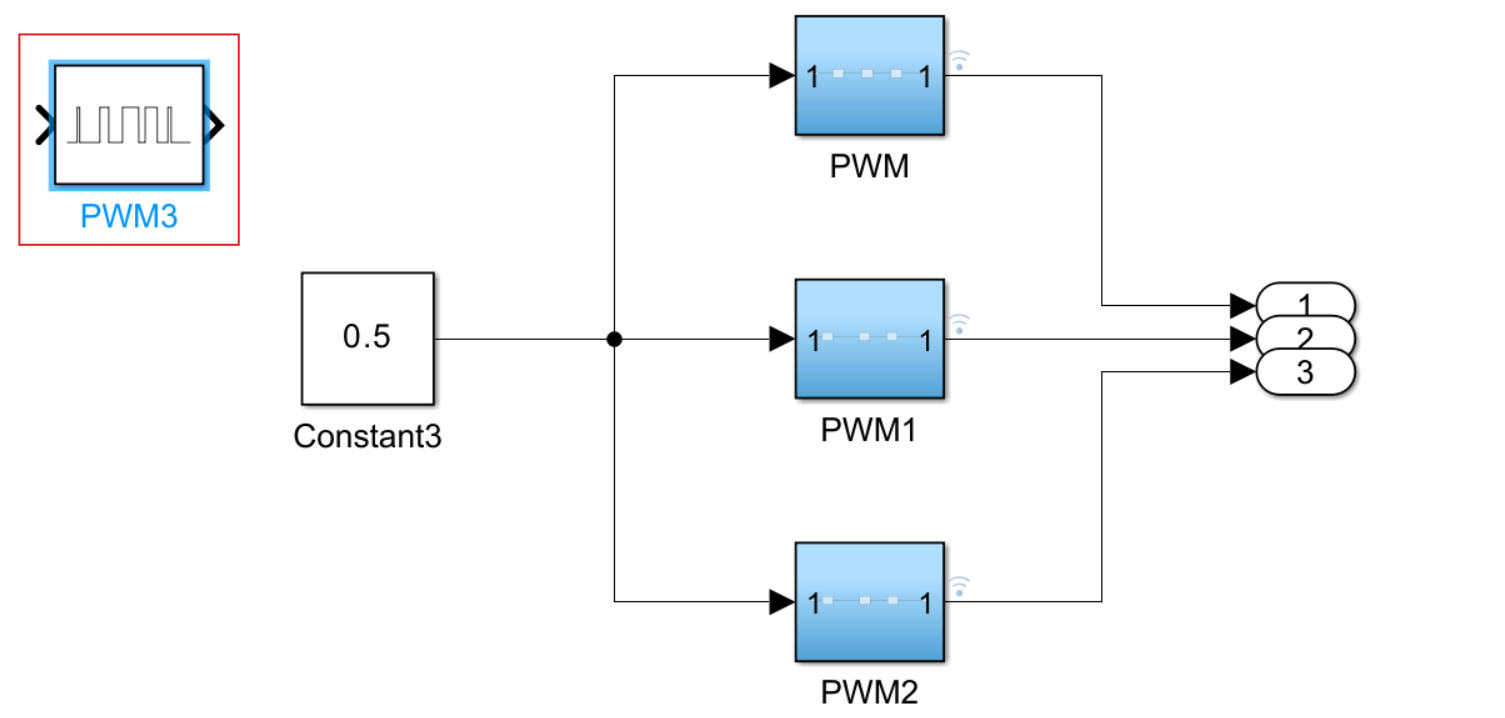

open multi_module_phase_shift_generator_built_in_pwm.slx

#### Resource Estimation

#### Critical Path Estimation